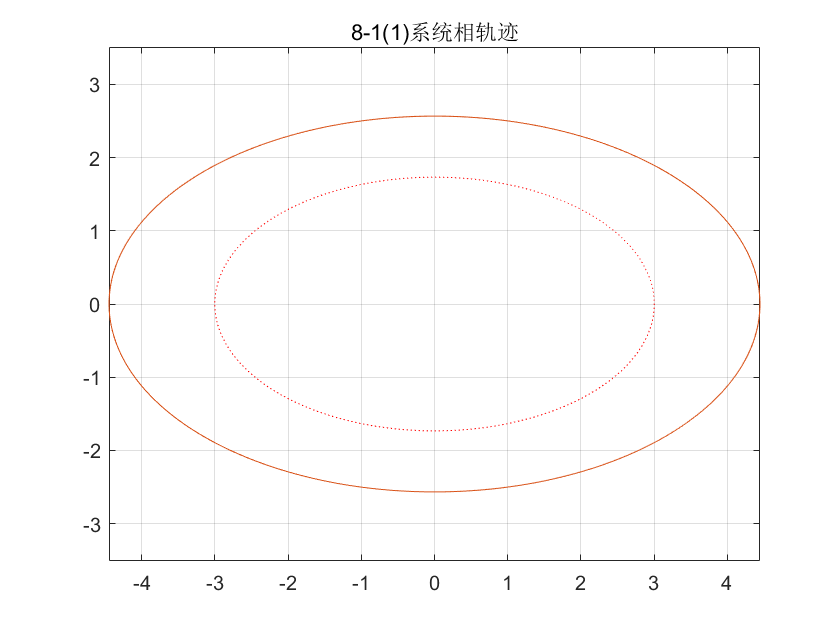

%8-1
clear 
t = 0:0.01:20;
e01 = [3 0];
e02 = [1 -2.5];
[t,e1] = ode45('sys81',t,e01);
[t,e2] = ode45('sys81',t,e02);
plot(e1(:,1),e1(:,2),'r:',e2(:,1),e2(:,2));
title('8-1(1)系统相轨迹');
axis equal,grid on;

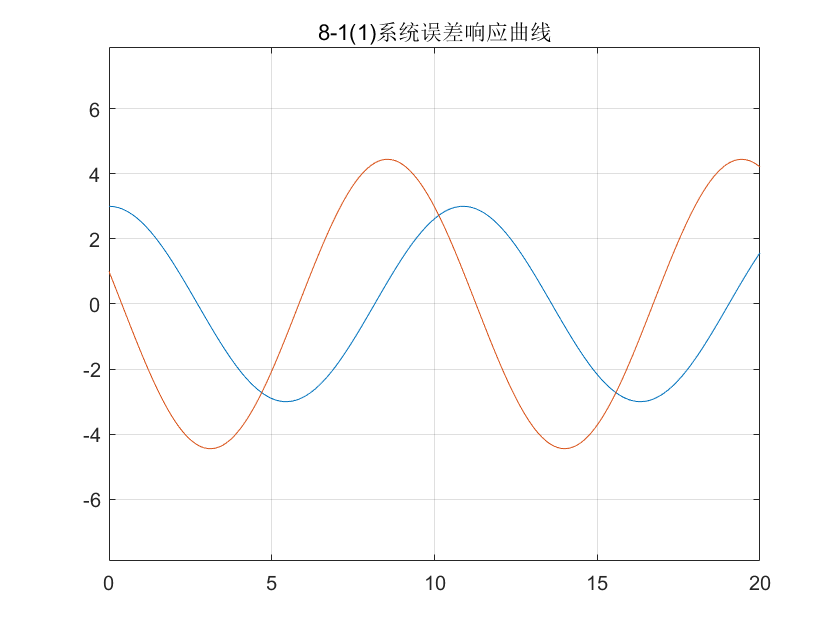

plot(t,e1(:,1),t,e2(:,1));
title('8-1(1)系统误差响应曲线');
axis equal,grid on;

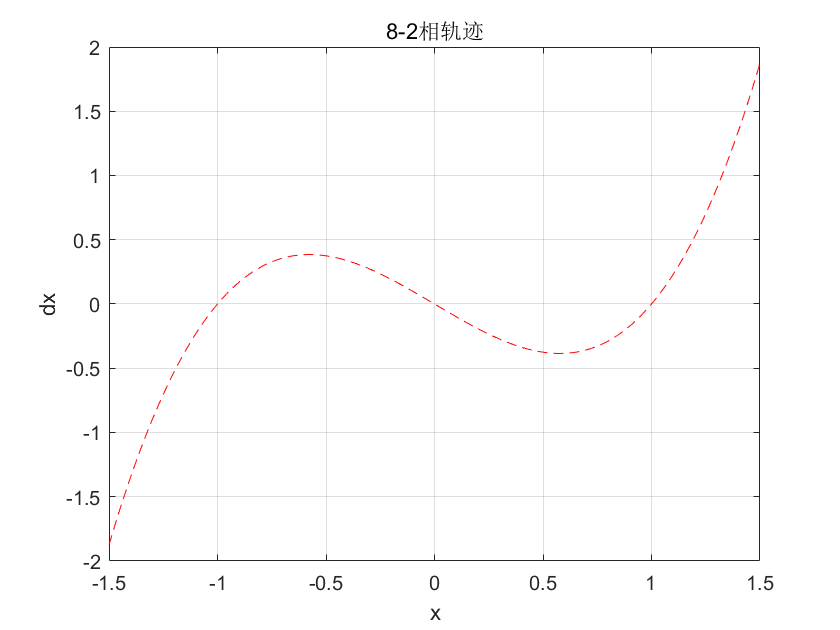

%8-2
clear
x = -1.5:0.001:1.5;
dx = -x + x.^3;
plot(x,dx,'r--'),grid on;
title('8-2相轨迹');
xlabel('x'),ylabel('dx');

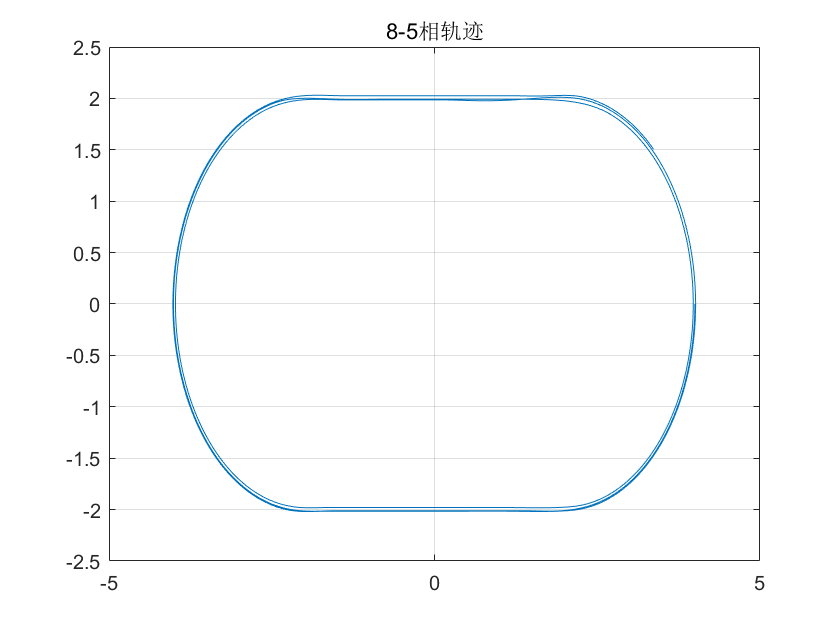

%8-5
clear
t = 0:0.01:30;
e0 = [4 0]';
[t,e] = ode45('sys85',t,e0);
plot(e(:,1),e(:,2)),grid on;
title('8-5相轨迹')

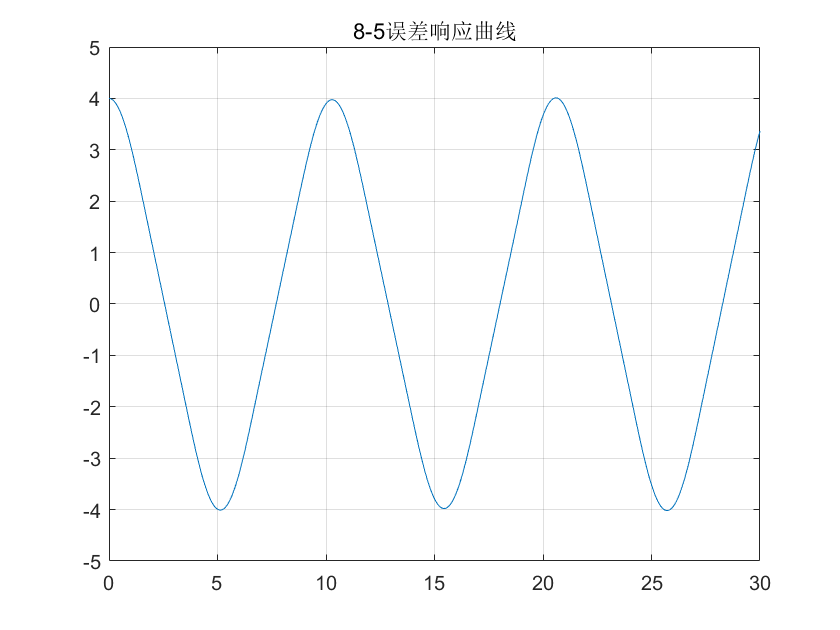

plot(t,e(:,1)),grid on;
title('8-5误差响应曲线');

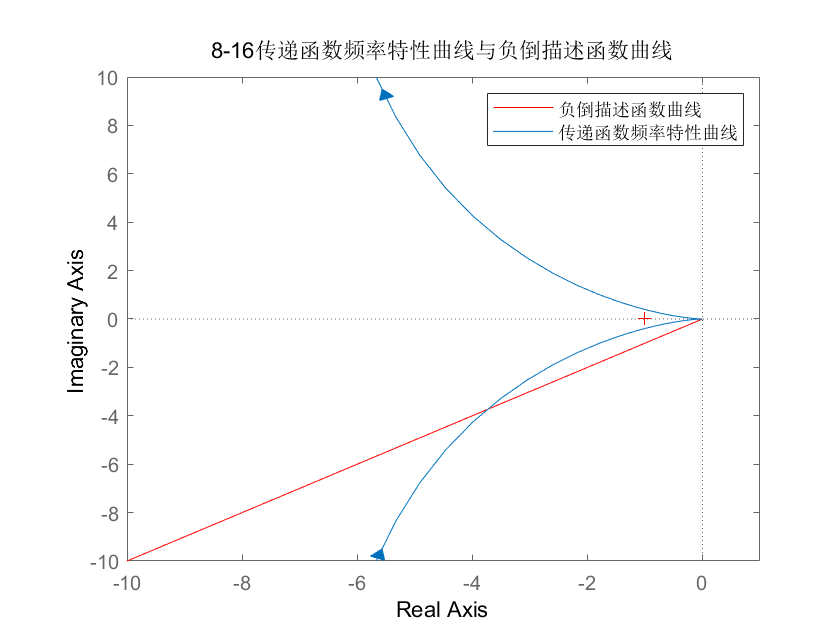

%8-16
clear
G = tf([15],[0.5 1 0]);
A = 0:0.01:100;
N1 = -A*exp(0.25*pi*1j);
x = real(N1);
y = imag(N1);
plot(x,y,'r'),hold on;
nyquist(G),hold off;
axis([-10,1,-10,10]);
legend('负倒描述函数曲线','传递函数频率特性曲线');
title('8-16传递函数频率特性曲线与负倒描述函数曲线');

%%w = 2.01
w = input('传递函数频率特性曲线与负倒描述函数曲线交点为自振频率w = ');
syms s
s = w*1j;
Gw = 15/(s*(0.5*s+1));
A = norm(Gw)

A = 5.2637

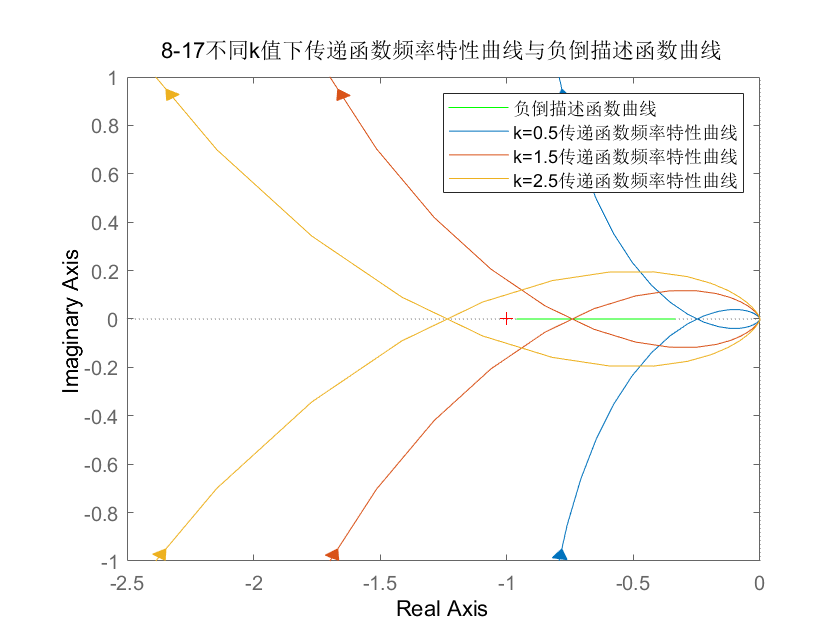

%8-17
clear
A = 0.01:0.01:100;
x = real(-(A+2)./(A+6));
y = imag(-(A+2)./(A+6));
plot(x,y,'g'),hold on;
k = [0.5 1.5 2.5];
for i =1:1:3
    G = zpk([],[0 -1 -1],k(i));
    nyquist(G),hold on;
end
legend('负倒描述函数曲线','k=0.5传递函数频率特性曲线','k=1.5传递函数频率特性曲线','k=2.5传递函数频率特性曲线');
title('8-17不同k值下传递函数频率特性曲线与负倒描述函数曲线');
axis([-2.5,0,-1,1]),hold off;

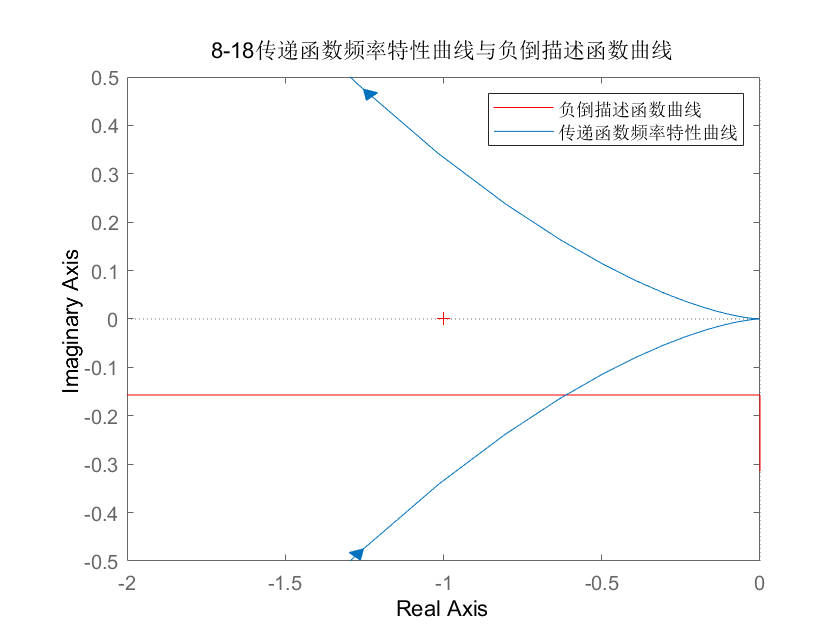

%8-18
clear
G = zpk([],[0 -1],10);
A = 0.01:0.01:10;
NA1 = -0.25*pi.*A.*sqrt(1-(0.2./A).^2)-1i*0.2*pi/4;
x = real(NA1);
y = imag(NA1);
plot(x,y,'r'),hold on;
nyquist(G),hold off;
axis([-2 0 -0.5 0.5]);
legend('负倒描述函数曲线','传递函数频率特性曲线');
title('8-18传递函数频率特性曲线与负倒描述函数曲线');

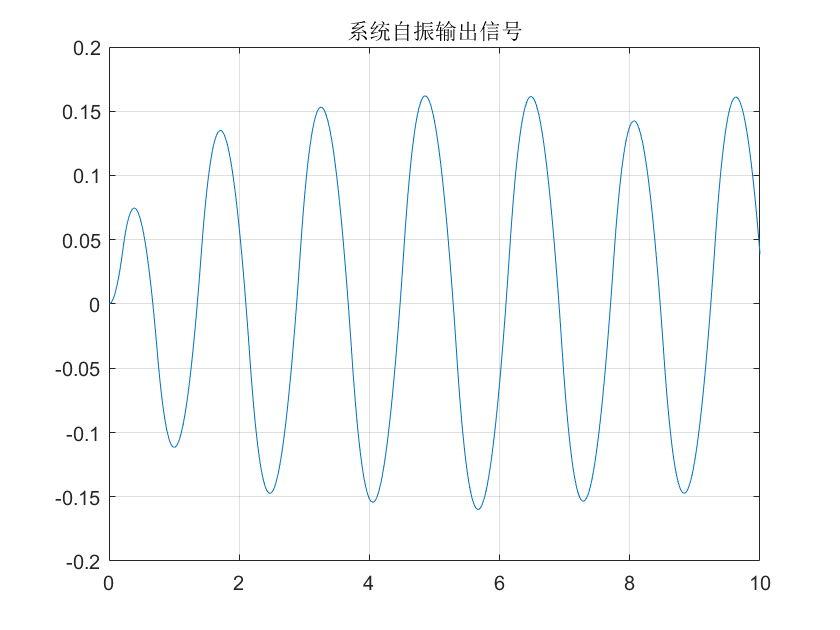



t = 0:0.01:10;
c0 = [0 0]';
[t,c1] = ode45('sys818',t,c0);
plot(t,c1(:,1)),grid on;
title('系统自振输出信号')

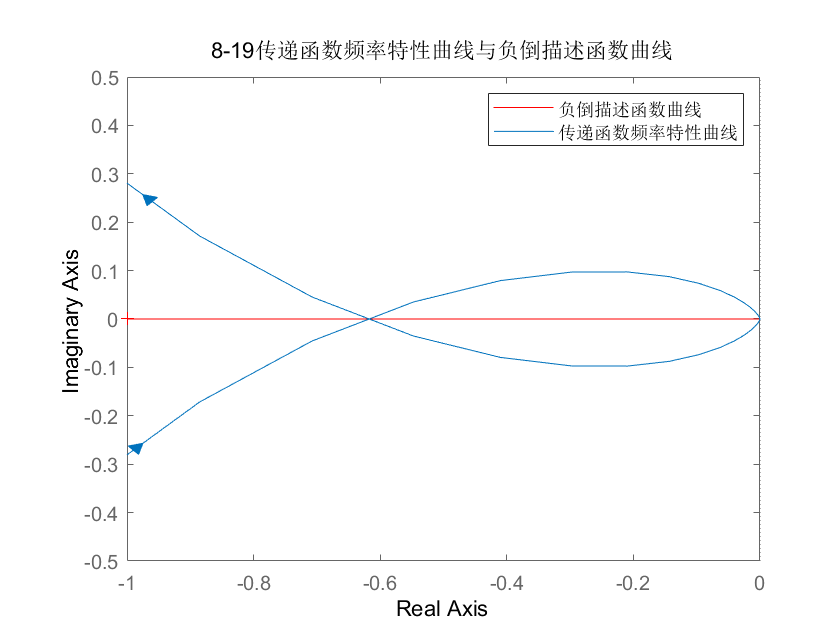

%8-19
clear
A = 0.01:0.01:1000;
NA1 = -4./(pi*A);
x = real(NA1);
y = imag(NA1);
plot(x,y,'r'),hold on;
G = zpk([],[0 -2 -2],10);
nyquist(G),hold off;
axis([-1 0 -0.5 0.5]);
legend('负倒描述函数曲线','传递函数频率特性曲线');
title('8-19传递函数频率特性曲线与负倒描述函数曲线');

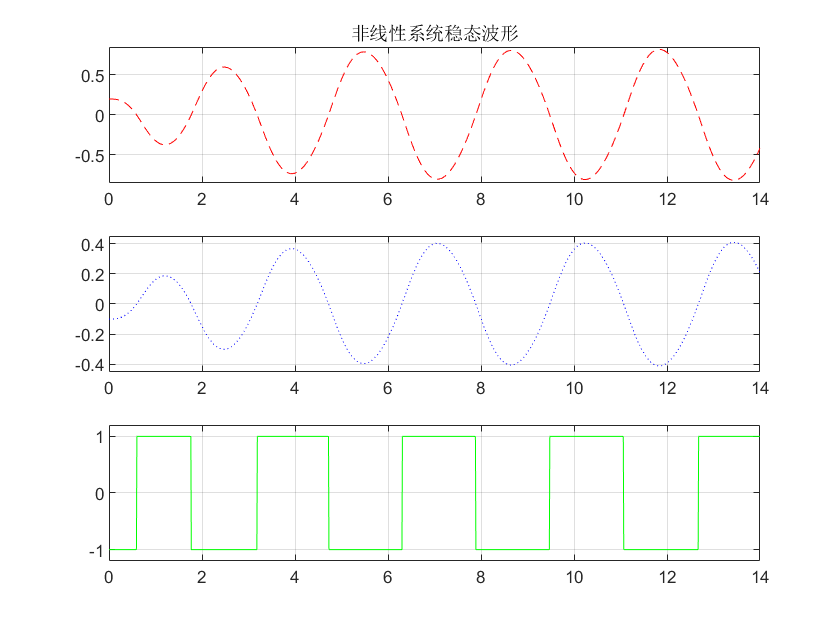


t = 0:0.01:14;
c0 = [-0.1 0 0]';
[t,c] = ode45('sys819',t,c0);
y = sign(c(:,1));
subplot(3,1,1);
plot(t,-2*c(:,1),'r--'),grid on;
axis([0 14 -0.85 0.85]);
title('非线性系统稳态波形')

subplot(3,1,2);
plot(t,c(:,1),'b:'),grid on;
axis([0 14 -0.45 0.45]);

subplot(3,1,3);
plot(t,y,'g-'),grid on;
axis([0 14 -1.2 1.2]);

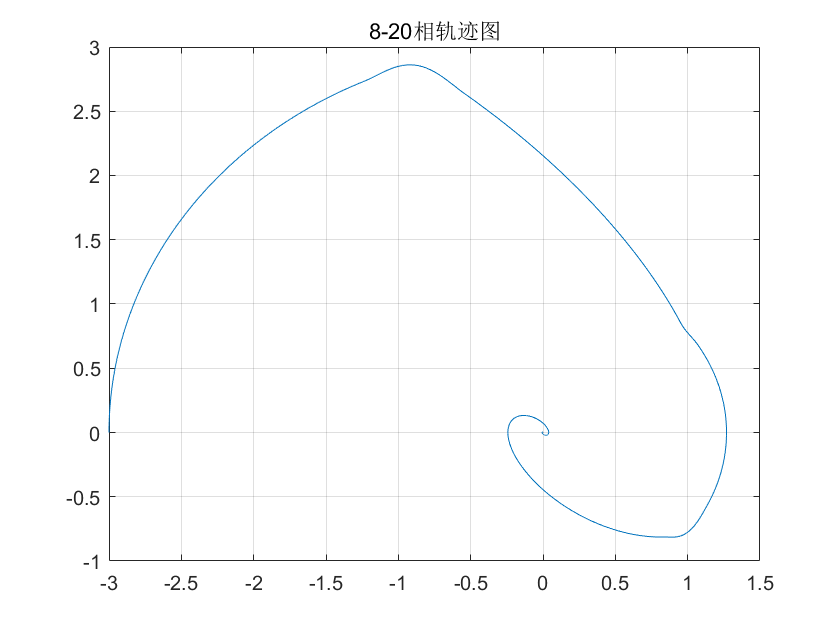

%8-20
clear
figure();
t = 0:0.01:50;
e0 = [-3 0]';
[t,e] = ode45('sys820',t,e0);
plot(e(:,1),e(:,2)),grid on;
title('8-20相轨迹图');

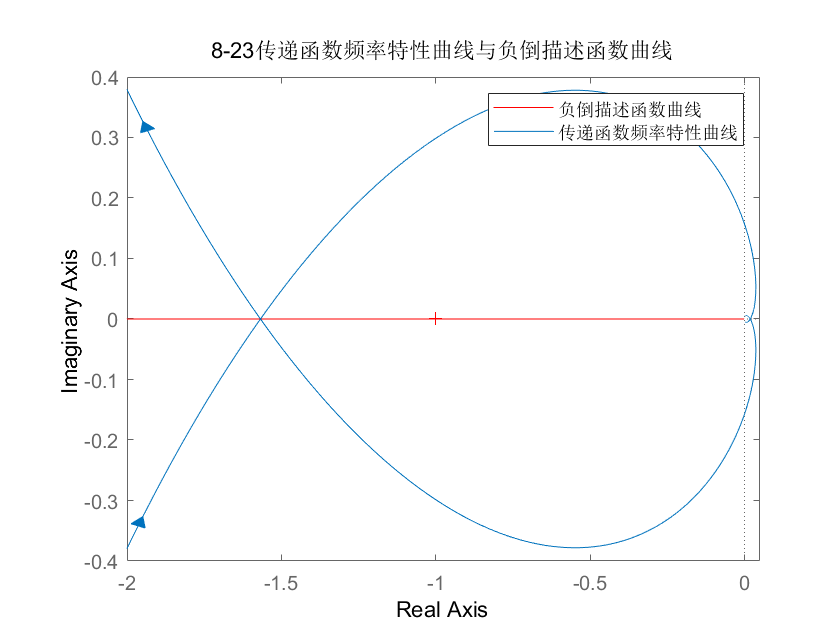

%8-23
clear
K = 4.97;tao = 0.32;
G = zpk([],[0 -1 -2],K,'inputdelay',tao);
A = 0.01:0.01:1000;
NA1 = -4./(pi*A);
x = real(NA1);
y = imag(NA1);
plot(x,y,'r'),hold on;
w = 0:0.01:10;
nyquist(G,w),hold off;
legend('负倒描述函数曲线','传递函数频率特性曲线');
title('8-23传递函数频率特性曲线与负倒描述函数曲线');

axis([-2 0.05 -0.4 0.4]);

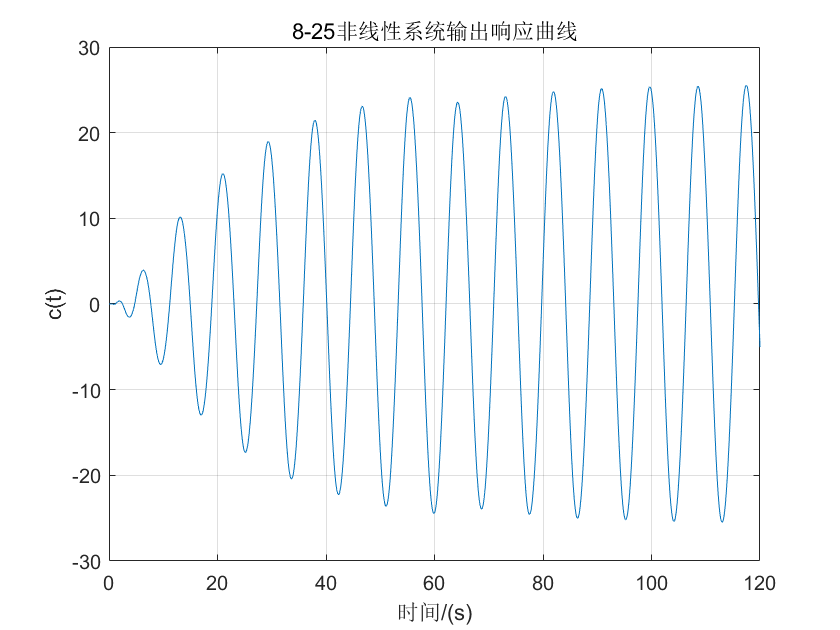

%8-25
clear
t = 0:0.01:120;
c0 = [0 0 0]';
[t,c] = ode45('sys825',t,c0);
plot(t,c(:,1)),grid on;
title('8-25非线性系统输出响应曲线');
xlabel('时间/(s)');
ylabel('c(t)');